Q1 - Function 1 using the normal equations method

format long
% initialize variables for all the functions
syms f1(t) f2(t) f3(t)

% import the data
data = importdata('Ass_2_Q1_data.txt');

lenData = length(data);
A1 = ones(lenData, 3);
B1 = zeros(lenData, 1);

% create the desired matrices 
for i=1:lenData
    A1(i,2) = data(i,1);
    A1(i,3) = data(i,1)^2;
    B1(i) = data(i,2);
end

A_T1 = transpose(A1);
sqr1 = A_T1*A1;
ATB1 = A_T1*B1;
% calculate the upper and lower triangle using cholosky
L1 = chol(sqr1, 'lower');
L_T1 = chol(sqr1, 'upper');

z1 = inv(L1)*ATB1;
x1 = inv(L_T1)*z1;
x1 = x1

x1 =    0.250922262575244
  -0.111345919449174
   0.009651643345421


% compare with the using the equation
x1 = inv(sqr1)*ATB1

x1 =    0.250922262575244
  -0.111345919449175
   0.009651643345421


% show the final function
f1(t) = x1(1) + x1(2)*t + x1(3)*t^2;

% calculate the Standard Error
Sr1 = sum((B1 - A1*x1).^2);
r1 = 1 - Sr1/sum((B1 - mean(B1)).^2)

r1 =    0.103730806718611


syx1 = sqrt(Sr1/(lenData - length(x1)))

syx1 =    0.254121724190224


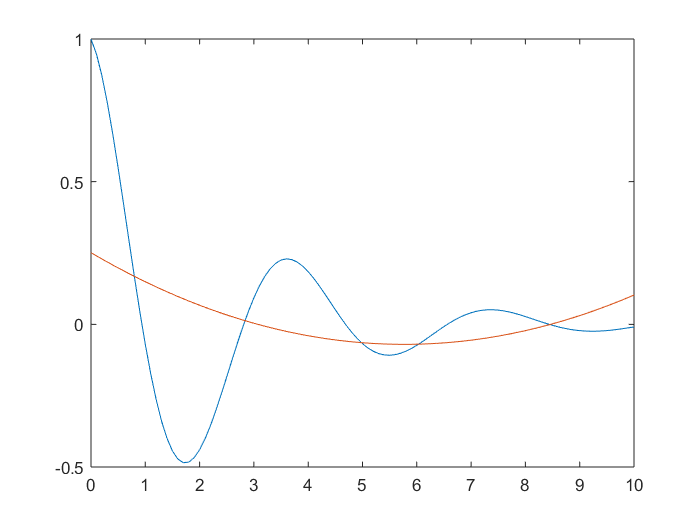

plot(data(:,1), data(:,2))
hold on
fplot(f1(t), [0,10])
hold off 

Function 2 - 

A2 = ones(lenData-1, 2);
B2 = zeros(lenData-1, 1);

for i=2:lenData
    A2(i-1, 2) = log(data(i,1));    
    B2(i-1) = log(data(i,2));
end

% calculate using normal equations method
A_T2 = transpose(A2);
sqr2 = A_T2*A2;
ATB2 = A_T2*B2;
% calculate the upper and lower triangle using cholosky
%L2 = chol(sqr2, 'lower');
%L_T2 = chol(sqr2, 'upper');

%z2 = inv(L2)*ATB2;
%x2 = inv(L_T2)*z2;
%x_comp = x2
%x2 = real(transpose(x2))
% compare with the using the equation
x2 = inv(sqr2)*ATB2;
x2 = [exp(x2(1)); x2(2)];
x_comp = x2

x_comp =   0.072688765244002 + 0.294592186754100i
 -1.109434267418068 + 0.275376751272873i


x2 = real(transpose(x2))

x2 =    0.072688765244002  -1.109434267418068


f2(t) = x2(1)*t^(x2(2))

$$f2(t) = \frac{5237777537070565}{72057594037927936\,t^{624555969167009/562949953421312}}$$

% calculate the Standard Error
Sr2 = abs(real(sum((B2 - A2*x_comp).^2)));
%r2 = 1 - Sr2/sum((B2 - mean(B2)).^2)
syx = sqrt(Sr2/(lenData-1 - length(x_comp)))

syx =    1.023766013230174


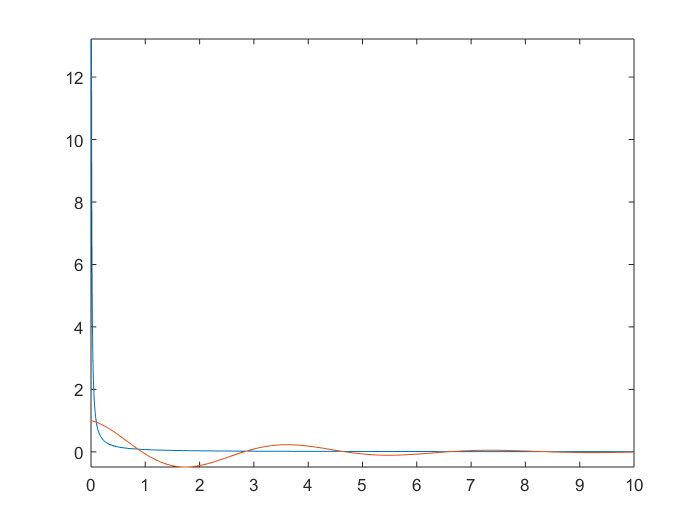

fplot(f2(t), [0,10])
hold on
plot(data(:,1), data(:,2))
hold off

Function 3 

A3 = ones(lenData, 2);
B3 = zeros(lenData, 1);

for i=1:lenData
    A3(i, 1) = 1;
    A3(i, 2) = data(i,1);
    
    B3(i) = 1/data(i,2);
end

% calculate using normal equations method
A_T3 = transpose(A3);
sqr3 = A_T3*A3;
ATB3 = A_T3*B3;

% calculate the upper and lower triangle using cholosky
%L3 = chol(sqr3, 'lower');
%L_T3 = chol(sqr3, 'upper');

%z3 = inv(L3)*ATB3;
%x3 = inv(L_T3)*z3;
%x3 = transpose(x3)
% compare with the using the equation
x3 = inv(sqr3)*ATB3

x3 =    2.403590506890200
  -1.744846214839930


f3(t) = ((x3(1) + x3(2).*t)).^(-1)

$$f3(t) = -\frac{1}{\frac{7858088762971929\,t}{4503599627370496}-\frac{676550581948873}{281474976710656}}$$

% calculate the Standard Error and regression
Sr3 = sum((B3.^(-1) - A3*x3).^2);
r3 = 1 - Sr3/sum((B3 - mean(B3)).^2)

r3 =    0.988676544514084


syx = sqrt(Sr3/(lenData - length(x3)))

syx =    8.185803381515331


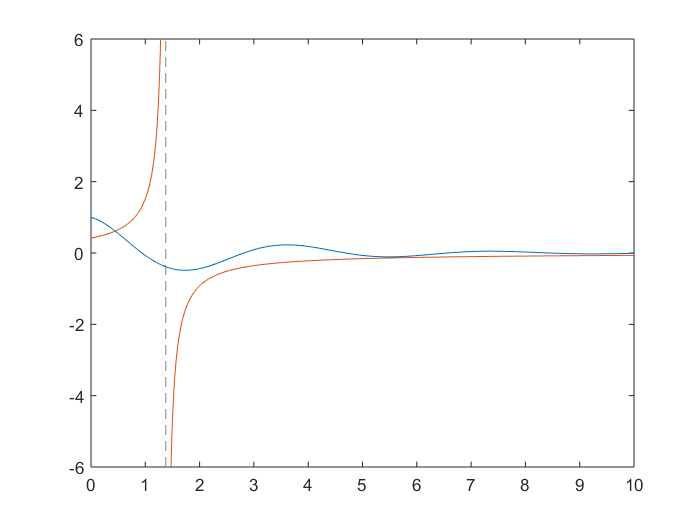

%y = ((x3(1) + x3(2).*data(:,1))).^(-1);
%plot(data(:,1), data(:,2), 'r-*', data(:,1), y, 'k');

plot(data(:,1), data(:,2))
hold on
fplot(f3(t), [0,10])
hold off